# Wavelet Scalogram Feature Generator

This script is intended to service as an example of how to load, process, and generate wavelet scalogram features from an audio file.

## List files

Find all data files in the '\EnvNoiseDetector\data\DataExamplesv2' directory. 

% Find base directory
basedir = fileparts(pwd);

% Feature storage directory and file name
featuredir = fullfile(basedir,"data","Features");
featurefilename = "FeaturesSNR6WaveletFeaturesv1";

% Find data examples directory
datadir = fullfile(basedir,"data","DataExamplesv2");

% File descriptions
fileDescripts = readtable(fullfile(datadir,"FileDescriptions.xlsx"),'TextType','string');
fileDescripts.AircraftPresent = fileDescripts.AircraftPresent == "Y";
fileDescripts.Contaminated = fileDescripts.Contaminated == "Y";

contaminationFiles = fileDescripts.FileName(fileDescripts.Contaminated);
signalFiles = fileDescripts.FileName(~fileDescripts.Contaminated);

% Create image output directories
signalImagesDir = fullfile(featuredir, "Images", "Signal");
contaminationImagesDir = fullfile(featuredir, "Images", "Contamination");
if ~exist(signalImagesDir, "dir")
    mkdir(signalImagesDir);
end
if ~exist(contaminationImagesDir, "dir")
    mkdir(contaminationImagesDir);
end

% Create pool of MATLAB workers
tic; parpool('local',4); toc

## Processing parameters

List and define processing parameters.

% processing type
type = "WaveletScalogram";

% record or block duration (s)
tblock = 3;

% fractional overlap between blocks, 0 <= foverlap <= 1
foverlap = 0.25;

% frequency limits for octave
freqlim = [30 20000];

% Signal to noise ratio
snrdB = 6;

## Signal files

Process clean signal files and store features. 

This takes about 30 minutes on a Core i7-7700k quad-core processor with 16 GB ram and 4 MATLAB parallel workers.

% Loop over all signal files
tic
parfor ifile = 1:length(signalFiles)
    % Load file
    [x,fs] = audioread(fullfile(datadir,signalFiles(ifile)));
    
    % Convert processing parameters to samples
    nblock = tblock*fs;
    noverlap = round(foverlap*nblock);
    
    xblock = spectralReshape(x,noverlap,nblock);
    
    % Process each block into a scalogram
    fileName = signalFiles(ifile).split(".");
    fileName = fileName(1);
    WaveletScalogramFeatures(xblock,224,224,fileName,signalImagesDir);
end

toc

Elapsed time is 1898.879527 seconds.


## Contamination

Now add contamination to the clean signals and generate features. Each clean signal will have a contamination signal randomly assigned to it and the contamination signal will be replicated to make the length of the clean signal. Then the two signals will be super imposed and processed to generate the features. 

This takes about 30 minutes on a Core i7-7700k quad-core processor with 16 GB ram and 4 MATLAB parallel workers.

% Make contamination signal assignments
% one contamination file index for each of the signal files
rng(42);
contaminationAssign = randi(length(contaminationFiles),1,length(signalFiles));

% Process signal files one at a time and add contamination signals
tic
xfeaturecell = cell(length(signalFiles),1);
parfor ifile = 1:length(signalFiles)
    contaminationFilesLocal = contaminationFiles;
    % Load files
    [x,fs] = audioread(fullfile(datadir,signalFiles(ifile)));
    [n,fn] = audioread(fullfile(datadir,contaminationFilesLocal(contaminationAssign(ifile))));
    assert(fs == fn,'featureGenerator:UnequalSampleRates',...
        'Sample rates for the signal data and the contamination data are not equal.')
    
    % Adjust contamination signal length
    n = repmat(n,ceil(length(x)/length(n)),1);
    n = n(1:length(x));
    
    % Convert processing parameters to samples
    nblock = tblock*fs;
    noverlap = round(foverlap*nblock);
    
    % Reshape into blocks
    xblock = spectralReshape(x,noverlap,nblock);
    n = spectralReshape(n,noverlap,nblock);
    
    % Super impose signal and noise together
    xblock = addNoise(xblock,n,snrdB);
    
    % Process each block into a scalogram
    fileName = signalFiles(ifile).split(".");
    fileName = fileName(1);
    contaminationFileName = contaminationFilesLocal(contaminationAssign(ifile)).split(".");
    contaminationFileName = contaminationFileName(1);
    WaveletScalogramFeatures(xblock,224,224,strcat(fileName,"_",contaminationFileName),contaminationImagesDir);
end

Writing out file amb01.wavSpectral reshape file amb01.wavAdd Noise file amb01.wavWavelet Scalogram Start file amb01.wavWavelet Scalogram End file amb01.wavWriting out file plane06.wavSpectral reshape file plane06.wavAdd Noise file plane06.wavWavelet Scalogram Start file plane06.wavWavelet Scalogram End file plane06.wavWriting out file plane05.wavSpectral reshape file plane05.wavAdd Noise file plane05.wavWavelet Scalogram Start file plane05.wavWavelet Scalogram End file plane05.wavWriting out file plane04.wavSpectral reshape file plane04.wavAdd Noise file plane04.wavWavelet Scalogram Start file plane04.wavWavelet Scalogram End file plane04.wavWriting out file plane03.wavSpectral reshape file plane03.wavAdd Noise file plane03.wavWavelet Scalogram Start file plane03.wavWavelet Scalogram End file plane03.wavWriting out file plane02.wavSpectral reshape file plane02.wavAdd Noise file plane02.wavWavelet Scalogram Start file plane02.wavWavelet Scalogram End file plane02.wavWriting out file pla

toc

Elapsed time is 2046.263348 seconds.


## Save output

Save the computed features to a zip archive.

% Save to file
zip(fullfile(featuredir,"WaveletScalograms.zip"),fullfile(featuredir,"Images"));

## GoogleNet Model

Use transfer learning with a pre-trained neural net to classify images.

This takes about 120 minutes on a Core i7-7700k quad-core processor with 16 GB ram.

allImages = imageDatastore(fullfile(featuredir,"Images"),...
    'IncludeSubfolders',true,...
    'LabelSource','foldernames');

rng(63)
[imgsTrain,imgsValidation] = splitEachLabel(allImages,0.8,'randomized');

Number of training images: 1488


Number of validation images: 372


net = googlenet;
lgraph = layerGraph(net);
lgraph = removeLayers(lgraph,{'pool5-drop_7x7_s1','loss3-classifier','prob','output'});

numClasses = numel(categories(imgsTrain.Labels));
newLayers = [
    dropoutLayer(0.6,'Name','newDropout')
    fullyConnectedLayer(numClasses,'Name','fc','WeightLearnRateFactor',5,'BiasLearnRateFactor',5)
    softmaxLayer('Name','softmax')
    classificationLayer('Name','classoutput')];
lgraph = addLayers(lgraph,newLayers);

lgraph = connectLayers(lgraph,'pool5-7x7_s1','newDropout');
inputSize = net.Layers(1).InputSize;

options = trainingOptions('sgdm',...
    'MiniBatchSize',15,...
    'MaxEpochs',20,...
    'InitialLearnRate',1e-4,...
    'ValidationData',imgsValidation,...
    'ValidationFrequency',10,...
    'ValidationPatience',Inf,...
    'Verbose',1,...
    'ExecutionEnvironment','cpu',...
    'Plots','training-progress');

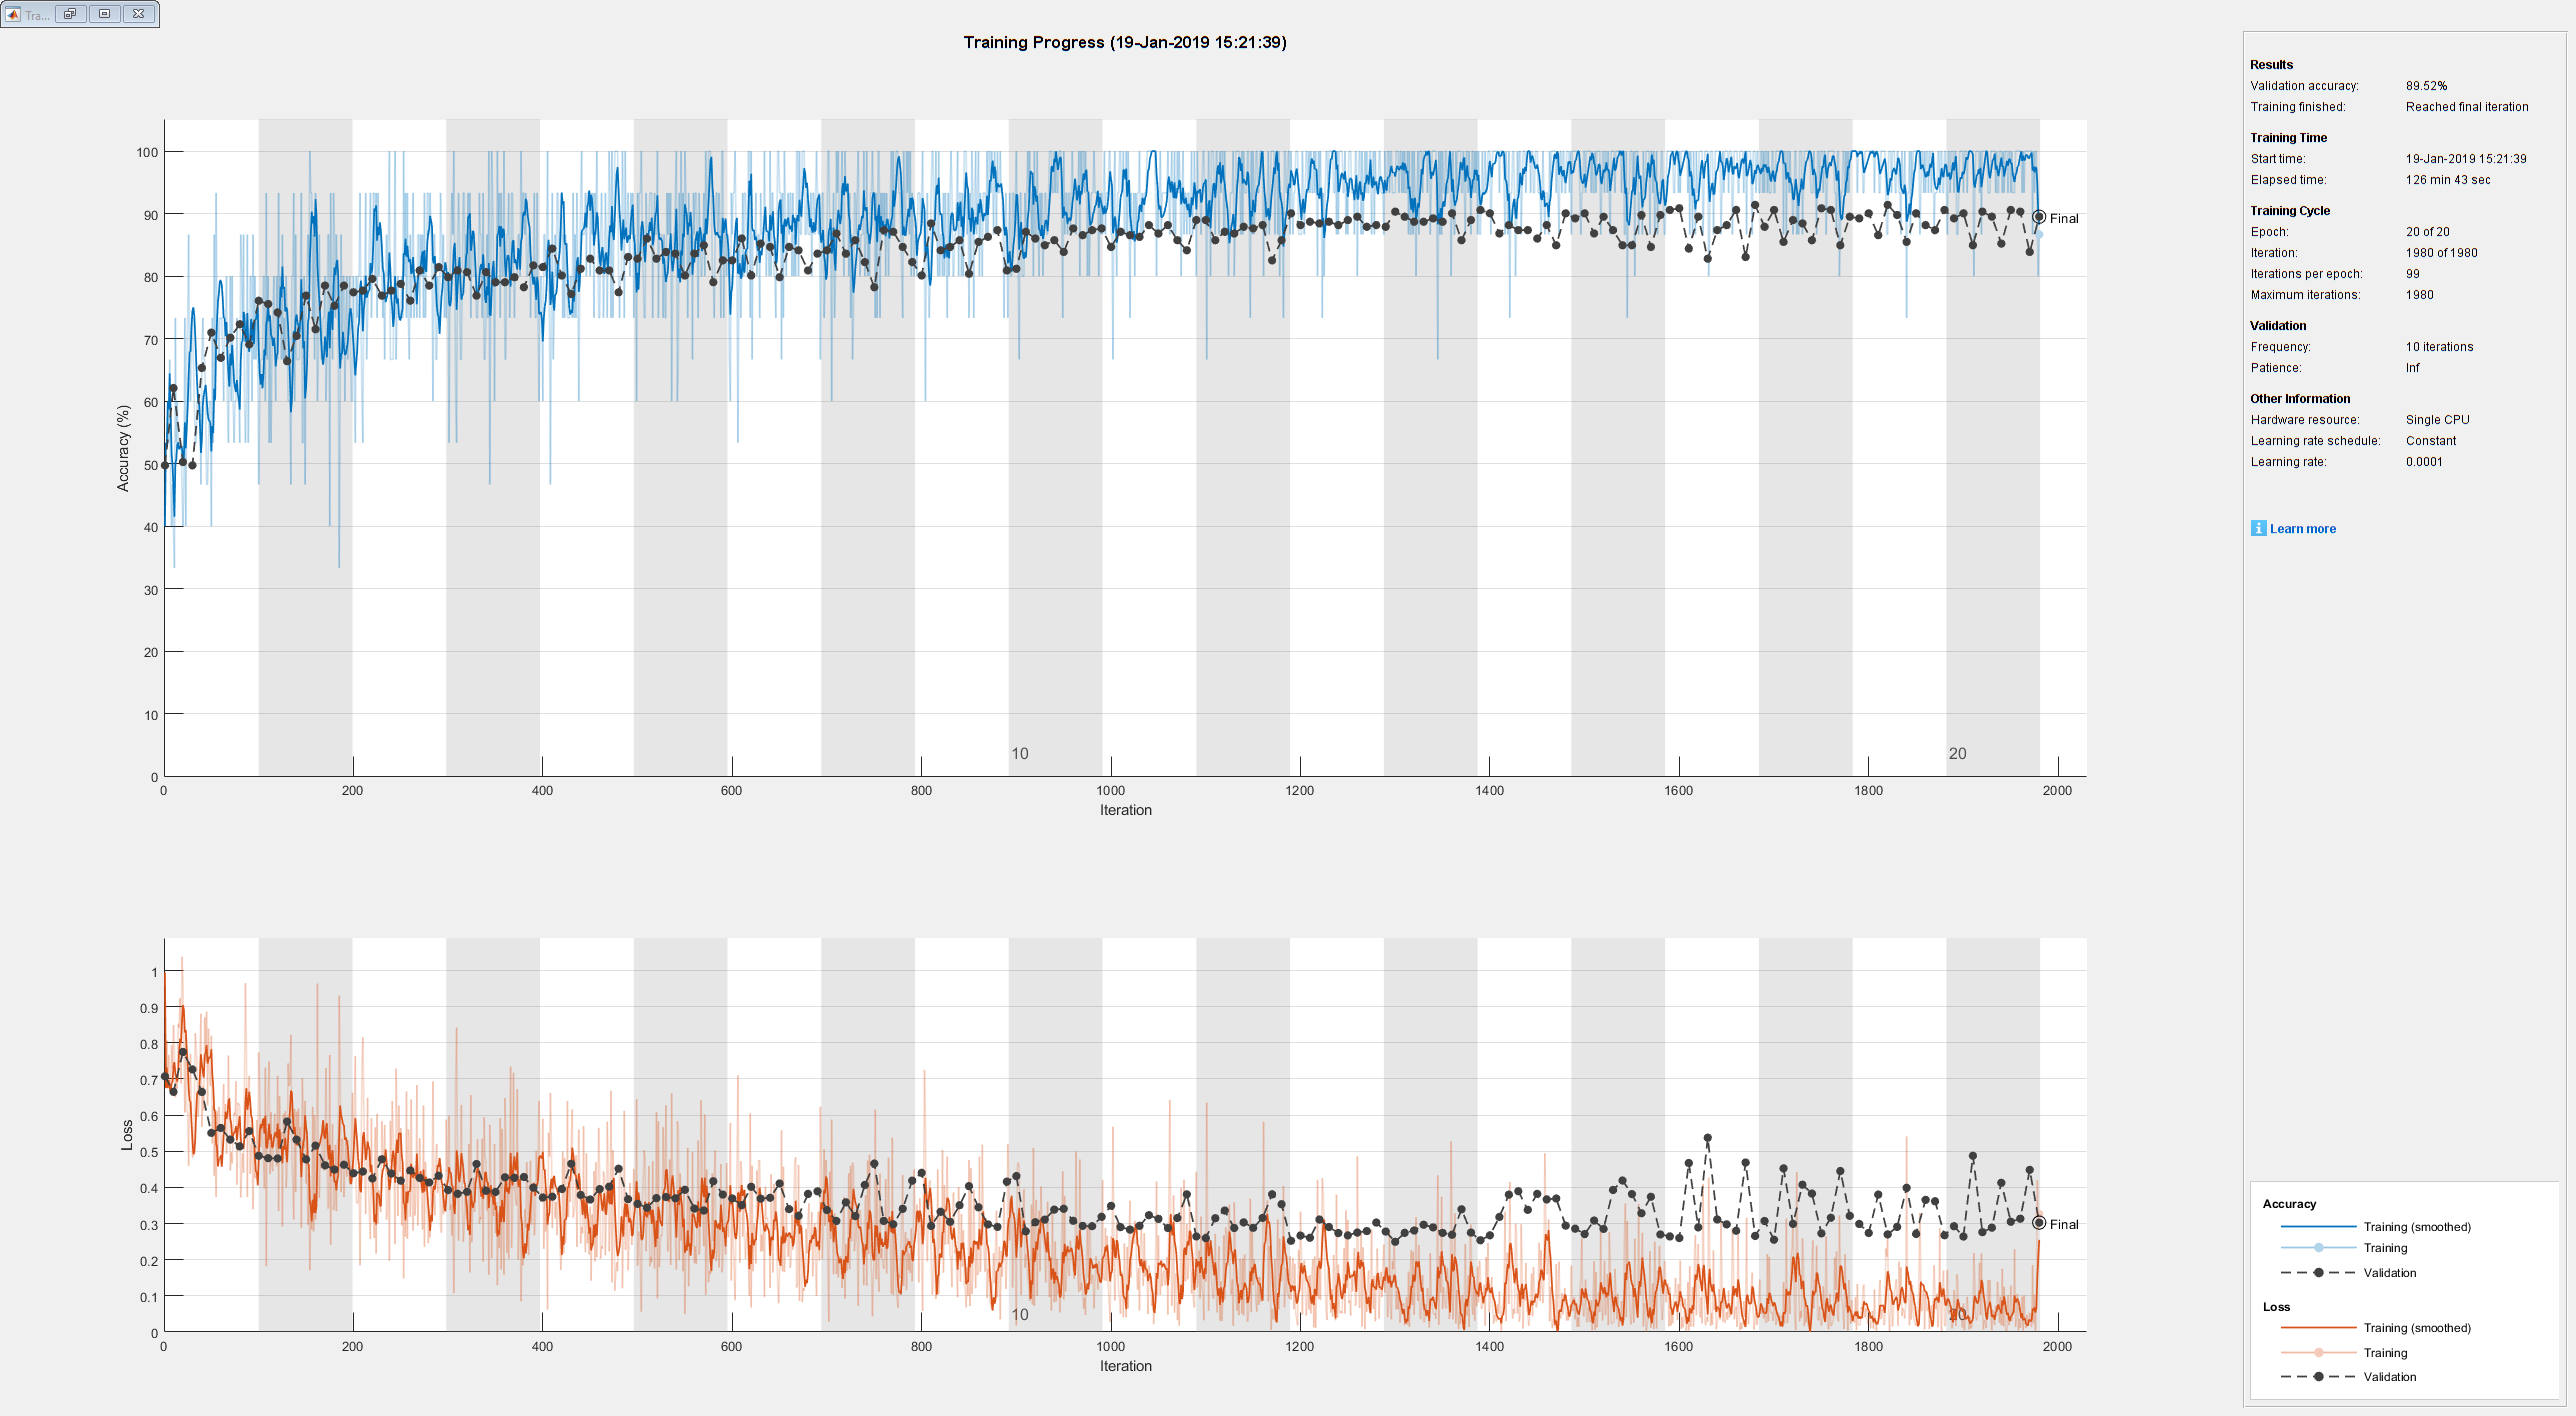

Initializing image normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:20 |       40.00% |       49.73% |       0.9941 |       0.7072 |      1.0000e-04 |
|       1 |          10 |       00:00:56 |       40.00% |       62.10% |       0.8491 |       0.6645 |      1.0000e-04 |
|       1 |          20 |       00:01:35 |       40.00% |       50.27% |       0.9689 |       0.7748 |      1.0000e-04 |
|       1 |          30 |       00:02:12 |       73.33% |       49.73% |       0.4822 |       0.7265 |      1.0000e-04 

rng(42)
trainedGN = trainNetwork(imgsTrain,lgraph,options);

The model ends up with 89.5% validation accuracy.

[YPred,probs] = classify(trainedGN,imgsValidation);
accuracy = mean(YPred==imgsValidation.Labels);
display(['GoogLeNet Accuracy: ',num2str(accuracy)]);

GoogLeNet Accuracy: 0.89516


save trainedGN

Error using save
Must be a string scalar or character vector.